# ENGR3390: Fun-Robo ACT Lab: Servos

Elvis Wolcott

Created 2/17/2021 - Revision 1

**Demonstration of using RCServoArduino()**

Aims a laser pointer using two servo motors attached to an Arduino-like microcontroller using PWM.

Works with the Spark Fun Wireless Motor Driver (DEV-14285), but should work with any Arduino setup wired the same.

The pan motor should be connected to PWM 9 and tilt to PWM 11.

The program prompts for positions 0-1 and then sets the position of the servo. Different servos have different ranges of motions, so we will measure the actual range and enter it to the program to produce a calibration graph.

## Document Code

clc
clear

## Stuff you run once

% COM port (CHECK THIS ON YOUR SYSTEM!)
port = 'COM12';
disp('note: It takes about 10 seconds to download new code to the Arduino');

note: It takes about 10 seconds to download new code to the Arduino


[robotArduino, panServo, tiltServo, blinkLED] = SETUPARDUINO(port);
% blink the on board LED
Blink(robotArduino, blinkLED, 3);
disp("Warning: Pan and Tilt Servos Active!");


% collected data
nTests = input(['Enter number of servo test positions, ' ...
    'followed by enter: ']);
 
% create a variable to hold experimental position data
panServoData = zeros(nTests,2);
tiltServoData = zeros(nTests, 2);

r = rateControl(0.25);                % create a 0.25 hz loop rate
reset(r);                             % reset loop time to zero

## Stuff you run multiple times

% test loop that collects samples
controlFlag = 1;                % loop progress
while (controlFlag < nTests+1)  % loop until flag is unset
    commandAngle = SENSE();     % desired angle from operator (used for both)
    panAngle = commandAngle;
    tiltAngle = commandAngle;
    THINK();                    % no op
    
    % set servo positions
    ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle);
    
    % store requested and actual positions
    panServoData(controlFlag, 1) = input("Enter actual pan angle (degrees):");
    panServoData(controlFlag, 2) = panAngle;
    tiltServoData(controlFlag, 1) = input("Enter actual tilt angle (degrees):");
    tiltServoData(controlFlag, 2) = tiltAngle;
    
    % blink to indicate completion
    Blink(robotArduino, blinkLED, 1);

    % loop iteration
    waitfor(r);
    controlFlag = controlFlag + 1;
end

## Mission Data Proccessing

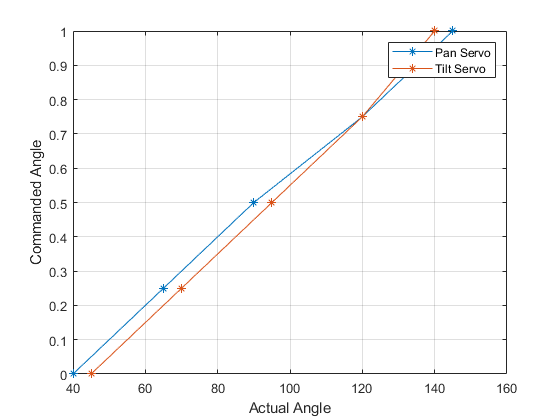

plot(panServoData(:, 1), panServoData(:, 2), '-*');
hold on;
plot(tiltServoData(:, 1), tiltServoData(:, 2), '-*');
hold off;
xlabel('Actual Angle');
ylabel('Commanded Angle');
legend('Pan Servo', 'Tilt Servo');
grid;

save calibration panServoData tiltServoData

Draw a Square

% pin for laser pointer
LASER = 'D12';
% delay (seconds) between movements
DELAY = 0.1; % much faster and it won't be a square!
% number of squares to draw
COUNT = 50;

% turn on the laser
configurePin(robotArduino, LASER, "DigitalOutput");
writeDigitalPin(robotArduino, LASER, 1);

% coordinates of box
y1 = 0.68;
y2 = 0.7;
x1 = 0.77;
x2 = 0.75;
% initial position
writePosition(tiltServo, y1);
writePosition(panServo, x1);

% draw a square
counter = 0;
while (counter < COUNT)
    % draw the sides
    pause(DELAY);
    writePosition(tiltServo, y2);
    pause(DELAY);
    writePosition(panServo, x2);
    pause(DELAY);
    writePosition(tiltServo, y1);
    pause(DELAY);
    writePosition(panServo, x1);
    counter = counter + 1;
end

% turn off the laser
writeDigitalPin(robotArduino, LASER, 0);

## Function Storage

function [robotArduino, panServo, tiltServo, blinkLED] = SETUPARDUINO(COMPORT)
    robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');
    
    blinkLED = 'D13';
    configurePin(robotArduino, blinkLED, "DigitalOutput");
    
    panServo = servo(robotArduino, 'D9', 'MinPulseDuration', 10*10^-6, 'MaxPulseDuration', 1925*10^-6);
    tiltServo = servo(robotArduino, 'D11', 'MinPulseDuration', 10*10^-6, 'MaxPulseDuration', 1925*10^-6);
    
    writePosition(panServo, 0.77);
    writePosition(tiltServo, 0.5);
    pause(5.0)
end

function [] =  Blink(a, LED, n)
    for bIndex=1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2)
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end
end

function commandAngle = SENSE()
    commandAngle = input('Enter desired angle (scale from 0-1): ');
end

function THINK()
end

function ACTRCServoArduino(panServo, tiltServo, panAngle, tiltAngle)
    % set position of two servos
    %writePosition(panServo, panAngle);
    writePosition(tiltServo, tiltAngle);
end
